# Homework

## task1

the equivalent governing equation is:


$$\nabla^2 u+1=0$$


below is the matlab code. This document is generated by matlab's script.

first read the triangulation mesh and draw the reigion, $b$ equals to 4.

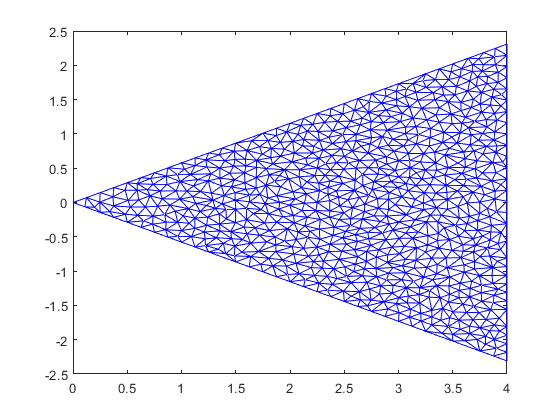

clear;clc;

b = 4;
alpha = 30*pi/180;
node_elem = textread('hw1.txt', '%d', 2);
node_num = node_elem(1);
elem_num = node_elem(2);
data = readmatrix('hw1.txt');
xy = data(1:node_num, 1:2);
Tri = round(data(node_num+1:node_num+elem_num, 2:4)) + 1;

triplot(Tri, xy(:, 1), xy(:, 2))

nodes at the boundary should be excluded, thus:

node_inside = [];
err = 1e-5;
for i = 1: node_num
    x = xy(i, 1);
    y = xy(i, 2);
    err1 = abs(x - b);
    err2 = abs(y - tan(alpha) * x);
    err3 = abs(y + tan(alpha) * x);
    if err1 > err && err2 > err && err3 > err
        node_inside = [node_inside, i];
    end
end

node_boundary = setdiff([1:node_num], node_inside);
node_boundary

node_boundary =      1     2     3     4     5     6     8    15    20    24    28    34    44    63    65    66    79    81    83   118   119   120   128   139   174   175   179   184   188   193   218   221   234   240   265   290   292   334   347   355   372   376   377   380   392   398   399   433   434   436


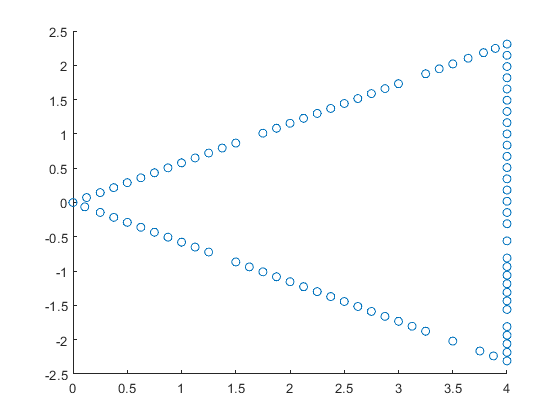

scatter(xy(node_boundary, 1), xy(node_boundary, 2))

now insert the local stiffness relationship into the total stiffness relationship to get a larger matrix:

K = zeros(node_num, node_num);
F = zeros(1, node_num);
u = zeros(1, node_num);
for k = 1: elem_num
    n1 = Tri(k, 1);
    n2 = Tri(k, 2);
    n3 = Tri(k, 3);
    x1 = xy(n1, 1);
    y1 = xy(n1, 2);
    x2 = xy(n2, 1);
    y2 = xy(n2, 2);
    x3 = xy(n3, 1);
    y3 = xy(n3, 2);
    A2 = 2*det([1 x1 y1; 1 x2 y2; 1 x3 y3]);
    k11 = (x2 - x3)^2 + (y2 - y3)^2;
    k12 = (x1 - x3) * (-x2 + x3) + (y1 - y3) * (-y2 + y3);
    k13 = (x1 - x2) * (x2 - x3) + (y1 - y2) * (y2 - y3);
    k22 = (x1 - x3)^2 + (y1 - y3)^2;
    k23 = -(x1^2 + x2 * x3 - x1 * (x2 + x3) + (y1 - y2) * (y1 - y3));
    k33 = (x1 - x2)^2 + (y1 - y2)^2;
    F1 = (x3 * (y1 - y2) + x1 * (y2 - y3) + x2 * (-y1 + y3)) / 6;
    F2 = (x3 * (y1 - y2) + x1 * (y2 - y3) + x2 * (-y1+y3)) / 6;
    F3 = (x3 * (y1 - y2) + x1 * (y2 - y3) + x2 * (-y1+y3)) / 6;
    K(n1, n1) = K(n1, n1) + k11 / A2;
    K(n1, n2) = K(n1, n2) + k12 / A2;
    K(n1, n3) = K(n1, n3) + k13 / A2;
    K(n2, n1) = K(n2, n1) + k12 / A2;
    K(n2, n2) = K(n2, n2) + k22 / A2;
    K(n2, n3) = K(n2, n3) + k23 / A2;
    K(n3, n1) = K(n3, n1) + k13 / A2;
    K(n3, n2) = K(n3, n2) + k23 / A2;
    K(n3, n3) = K(n3, n3) + k33 / A2;
    F(n1) = F(n1) + F1;
    F(n2) = F(n2) + F2;
    F(n3) = F(n3) + F3;
end

K

K =     0.5893         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.5893         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

isdiag(K)

ans = logical
   0


F

F =     0.0026    0.0026    0.0030    0.0084    0.0137    0.0072    0.0168    0.0057    0.0149    0.0136    0.0132    0.0132    0.0135    0.0111    0.0096    0.0106    0.0132    0.0178    0.0113    0.0089    0.0128    0.0141    0.0119    0.0114    0.0087    0.0118    0.0107    0.0080    0.0092    0.0126    0.0126    0.0171    0.0149    0.0074    0.0114    0.0143    0.0114    0.0129    0.0160    0.0126    0.0102    0.0136    0.0128    0.0081    0.0166    0.0129    0.0146    0.0110    0.0190    0.0119


inverse the $K$ to get the result:

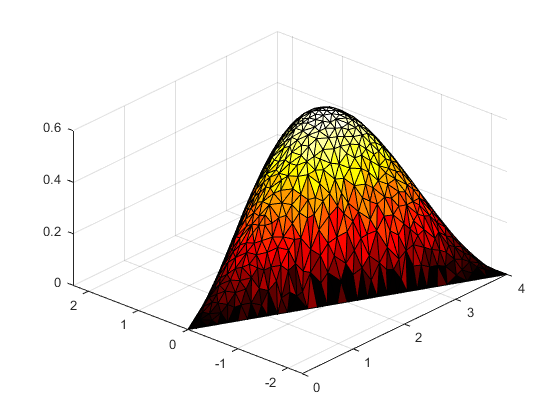

u(node_inside) = K(node_inside, node_inside) \ F(node_inside).';
trisurf(Tri, xy(:, 1), xy(:, 2), u)
colormap hot;

view([-48.300 40.800])

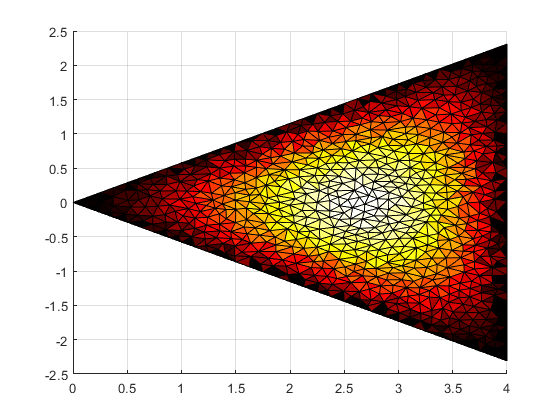

view([-0.600 90.000])

## task2

the Lagrange equation is as below:


$$\frac{d}{dt}\frac{\partial L}{\partial \dot{q}_i}-
\frac{\partial L}{\partial q_i}=0\quad 
i=1,2,3\dots$$


where $L$ equals to:


$$L=T-V$$


in which $T$ is the kinetic energy and $V$ is potenial energy. In this case, let $\theta_1=q_1\quad \theta_2=q_2$：


$$\begin{cases}
&\vec{u}_1=
    (l_1 \dot{\theta}_1 \cos \theta_1 + \dot{f})\vec{i}
    +
    l_1 \dot{\theta}_1 \sin\theta_1 \vec{j}\\
&\vec{u}_2=
    (l_1 \dot{\theta}_1 \cos \theta_1 + l_2 \dot{\theta}_2 \cos \theta_2 + \dot{f})\vec{i}
    +
    (l_1 \dot{\theta}_1 \sin\theta_1 + l_2 \dot{\theta}_2 \sin\theta_2)\vec{j}
\end{cases}$$


kietic energy $T$:


$$T=\frac{1}{2}m_1||u_1||^2+\frac{1}{2}m_2||u_2||^2$$


potential energy $V$:


$$V = m_1 g l_1 (1-\cos\theta_1) + m_2 g [l_1(1-\cos\theta_1) + l_2(1-\cos\theta_2)]$$


use Lagrange equation we will have the result:


$$\frac{d}{dt}
\frac{\partial L}{\partial \dot{\theta}_1}-\frac{\partial L}{\partial \theta_1}\rightarrow\\

(m_1+m_2)(\ddot{f}\cos\theta_1 + g\sin\theta_1 + l_1 \ddot{\theta}_1)
            +
            l_2m_2\dot{\theta}_2^2 \sin(\theta_1-\theta_2)
            +
            l_2 m_2 \ddot{\theta}_2
            \cos(\theta_1 - \theta_2)=0$$



$$\frac{d}{dt}
\frac{\partial L}{\partial \dot{\theta}_2}-\frac{\partial L}{\partial \theta_2}\rightarrow\\
\ddot{f}\cos\theta_2
            +
            g\sin\theta_2
            -
            l_1 \dot{\theta}_1^2 \sin(\theta_1 - \theta_2)
            +
            l_1 \ddot{\theta}\cos(\theta_1 - \theta_2)
            +
            l_2\ddot{\theta}_2 = 0$$


### task3

for this problem, use hermite interpolation to finish the job:

denote that:


$$x_2=x_1+h\\
x = x_1+t$$


clear;clc;

syms x x1 x2 h t;

mat = [
   1 x1 x1^2 x1^3;
   0 1 2*x1 3*x1^2;
   1 x2 x2^2 x2^3;
   0 1 2*x2 3*x2^2;
];
phi = simplify([1 x x^2 x^3] * inv(mat));
phi_local = subs(subs(phi, x2, x1+h), x, x1+t);
phi_local

$$phi\_local = \left(\begin{array}{cccc} \frac{{\left(h-t\right)}^{2}\,\left(h+2\,t\right)}{h^{3}} & \frac{t\,{\left(h-t\right)}^{2}}{h^{2}} & \frac{t^{2}\,\left(3\,h-2\,t\right)}{h^{3}} & -\frac{t^{2}\,\left(h-t\right)}{h^{2}} \end{array}\right)$$

simplify(diff(phi_local, t))

$$ans = \left(\begin{array}{cccc} -\frac{6\,t\,\left(h-t\right)}{h^{3}} & \frac{h^{2}-4\,h\,t+3\,t^{2}}{h^{2}} & \frac{6\,t\,\left(h-t\right)}{h^{3}} & -\frac{t\,\left(2\,h-3\,t\right)}{h^{2}} \end{array}\right)$$

thus we have when $0\leq t\leq h$:


$$w(x)=
\frac{(h-t)^2(h+2t)}{h^3}w_k+
\frac{t(h-t)^2}{h^2}\theta_k+
\frac{t^2(3h-2t)}{h^3}w_{k+1}
-\frac{t^2(h-t)}{h^2}\theta_{k+1}$$



$$\theta(x)=
-\frac{6t(h-t)}{h^3}w_k+
\frac{(h-t)(h-3t)}{h^2}\theta_k+
\frac{6t(h-t)}{h^3}w_{k+1}-
\frac{t(2h-3t)}{h^2}\theta_{k+1}$$


below is the caculation parameters:

clear;clc;

q = -200;
F = -1000;
M = 2000;
L = 0.12;
d1 = 0.03;
d2 = 0.02;
Es = 200e9;
J1 = pi * d1^4 / 64;
J2 = pi * d2^4 / 64;
N = 101;
x = linspace(0, 2*L, N);
h = 2*L / N;

the local stiffness matrix $K_{local}$ and $b_{local}$ are shown as below:

K = zeros(2*N, 2*N);
b = zeros(2*N);
stiffness_K = [12/h^3, 6/h^2, -12/h^3, 6/h^2;
   6/h^2, 4/h, -6/h^2, 2/h;
   -12/h^3, -6/h^2, 12/h^3, -6/h^2;
   6/h^2, 2/h, -6/h^2, 4/h];
stiffness_b = h * [1/2, h/12, 1/2, -h/12];
to_solve = [3:2*N-2, 2*N];
stiffness_K

stiffness_K = 	1.0e+08 *

    8.9436    0.0106   -8.9436    0.0106
    0.0106    0.0000   -0.0106    0.0000
   -8.9436   -0.0106    8.9436   -0.0106
    0.0106    0.0000   -0.0106    0.0000


stiffness_b

stiffness_b =     0.0012    0.0000    0.0012   -0.0000


put them together:

for k = 1: N-1
    if k <= (N-1)/2
        K(2*k-1:2*k+2, 2*k-1:2*k+2) = K(2*k-1:2*k+2, 2*k-1:2*k+2) + Es * J1 * stiffness_K;
        b(2*k-1:2*k+2) = b(2*k-1:2*k+2) + q * stiffness_b;
    else
        K(2*k-1:2*k+2, 2*k-1:2*k+2) = K(2*k-1:2*k+2, 2*k-1:2*k+2) + Es * J2 * stiffness_K;
    end
end
b(N) = b(N) + F;
b(2*N) = b(2*N) - M;

solve the $Ku=b$ and get $w_i,\theta_i$

bm = b(to_solve);
Km = K(to_solve, to_solve);
solution = zeros(2*N);
solution(to_solve) = Km \ bm.';
w = solution(1:2:2*N);
theta = solution(2:2:2*N);
w

w =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0010    0.0010    0.0011    0.0011    0.0011


theta

theta =          0    0.0006    0.0011    0.0017    0.0022    0.0028    0.0033    0.0038    0.0043    0.0048    0.0052    0.0057    0.0061    0.0066    0.0070    0.0074    0.0078    0.0082    0.0086    0.0090    0.0093    0.0097    0.0100    0.0103    0.0106    0.0109    0.0112    0.0115    0.0118    0.0120    0.0123    0.0125    0.0127    0.0129    0.0131    0.0133    0.0135    0.0136    0.0138    0.0139    0.0141    0.0142    0.0143    0.0144    0.0145    0.0145    0.0146    0.0146    0.0147    0.0147


here's the torsion angle $\theta(x)-x$

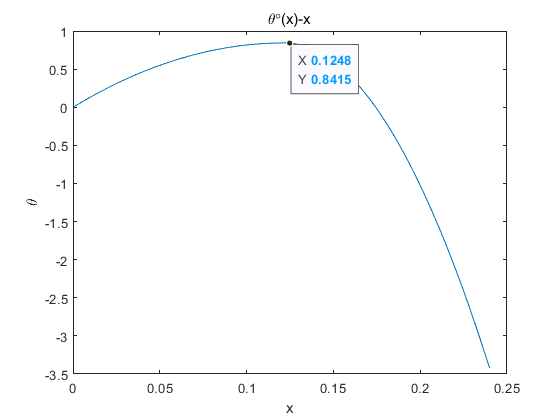

plot(x, theta*180/pi)
xlabel('x')
ylabel('\theta')
title('\theta\circ(x)-x')
ax = gca;
chart = ax.Children(1);
datatip(chart,0.1248,0.8415);

below is the deflection:

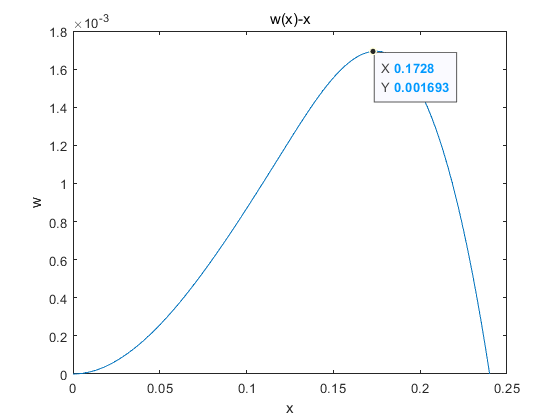

plot(x, w)
xlabel('x')
ylabel('w')
title('w(x)-x')

ax = gca;
chart = ax.Children(1);
datatip(chart,0.1728,0.001693);